# Elaborato sul calcolo parallelo matlab

### Ambiente

La test suite utilizzata è composta da un server Linux avente un i7-7700K  e una GPU Nvidia modello 750 con più di 300 CUDA Cores.

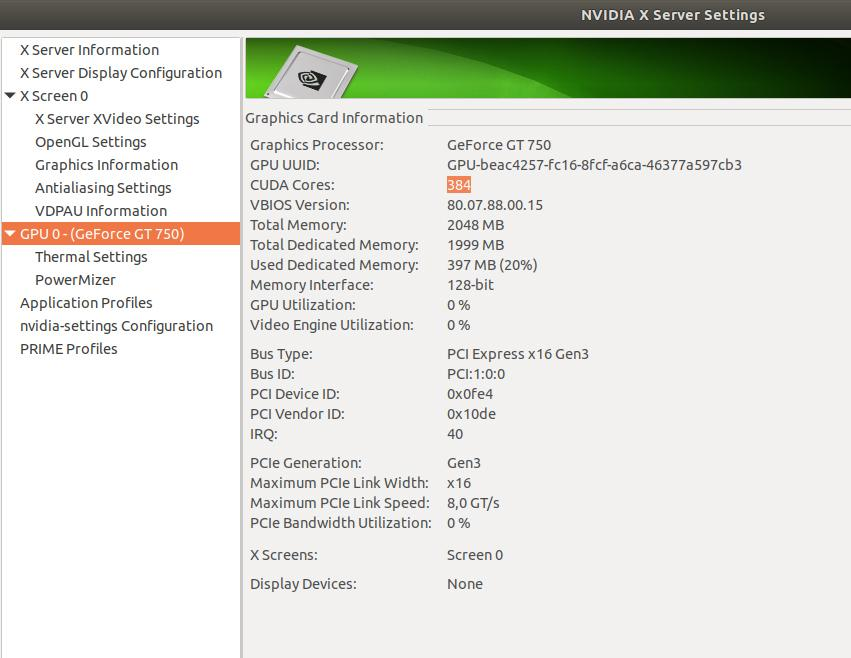

## Parallelizzazione a livello CPU Parfor-loop

Parfor-loop è un costrutto Matlab che permette di eseguire iterazioni for-loop in parallelo su workers.

Calcolo del raggio spettrale

Come esempio, proviamo a calcolare il prodotto matriciale di una serie di matrici generate casualmente e di dimensioni crescenti. Di seguito viene mostrato l'andamento delle prestazioni, in termini di tempo, migliorino utilizzando un loop parallelo piuttosto che un loop classico sequenziale:

%Prodotto matrici in parallelo
niter = [500 1000 5000 10000];
dim   = 1000;
v     = rand(dim*dim,1);
m     = reshape(v, dim, dim);
 
%Esecuzione sequenziale
for k=1:length(niter)
    tic;
    for i=1:niter(k)
        prod=m*m;
    end
    time(1,k)=toc;
end
 
%Esecuzione parallela
for k=1:length(niter)
    tic;
    parfor i=1:niter(k)
        prod=m*m;
    end
    time(2,k) = toc;
end

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).


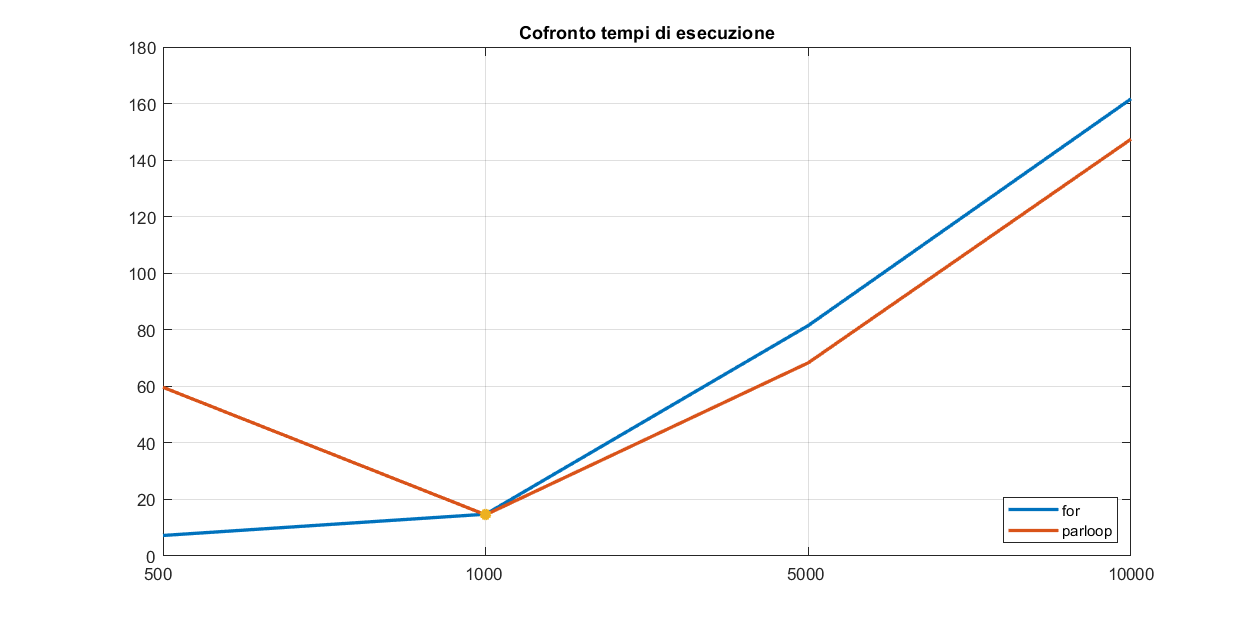

figure('Position', [250 250 1000 500])
plot(time.','LineWidth',2),title('Cofronto tempi di esecuzione'),hold on,grid on;
plot(2,14.58,'*','LineWidth',4)
legend('for','parloop','Location','southeast');
ax=gca;
ax.XTick=1:4;
ax.XTickLabel={niter};

Dal grafico dell'andamento dei tempi di esecuzione, è interessante notare, come per poche iterazioni il tempo impiegato dall'elaborazione con il **parloop** è maggiore rispetto al caso in cui si utilizza il **for**, questo è dovuto al tempo necessario per creare i worker, per suddividere il lavoro e fare la join dei risultati. Superato il punto di crossover, dove le due curve si incontrano, il **parloop** grantisce prestazoni migliori.

## Esempio di deep learning e addestramento di reti neurali mediante l'utilizzo della tecnologia CUDA delle GPU Nvidia

In questo elaborato mostreremo come utilizzare Matlab e il **Deep Learning Toolbox** per addestrare una rete neurale convolutiva a riconoscere un dataset di numeri compresi fra 0 e 9 scritti a mano, Il dataset è preso da uno dei tanti messi a disposizione da Matlab. Lo scopo dell'esempio è mostrare le potenzialità del `Matlab `nel utilizzare, nel modo più semplice, la **GPU** per eseguire operazioni parallelizzabili. Infatti il concetto dietro a questa tecnica di Inteligenza Artificiale è quella di fornire delle immagini base con la corretta etichetta che rappresentano la base di conoscenza iniziale, che dovrà essere migliorata, addestrandola, fornendogli delle nuove immagine che dovranno essere confrontate con le altre al fine di determinare similitudini per poterne riconoscere il significato. Proprio questo confronto può essere parallelizzato utilizzando la **GPU**.

## Inizializzazione

Per prima cosa carichiamo il path delle cifre `(digitsPath)` e successivamente creiamo il datastore associato ad esso, necessario per caricare in memoria elementi che normalmente non potrebbero entrarvi a causa della dimensione elevata del dataset [1].

digitsPath = fullfile(matlabroot,'toolbox','nnet','nndemos', ...
    'nndatasets','DigitDataset');
imds = imageDatastore(digitsPath, 'IncludeSubfolders', true, ...
    'LabelSource','foldernames');

Mostriamo alcune immagini del dataset utilizzato per l'apprendimento della rete in questione.

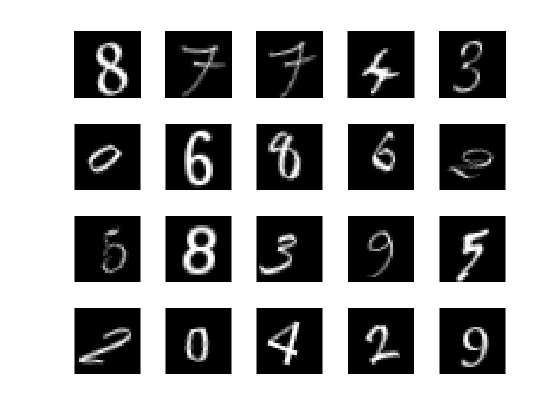

figure;
perm = randperm(10000,20);
for i = 1:20
    subplot(4,5,i);
    imshow(imds.Files{perm(i)});
end

Dividiamo il dataset in due sotto dataset, training e validation; il primo viene utilizzato dalla rete come apprendimento, il secondo viene utilizzato da noi per testare la rete se effettivamente ha raggiunto o meno un certo grado di affidabilità richiesta.

numTrainFiles = 750;
[imdsTrain,imdsValidation] = splitEachLabel(imds,numTrainFiles,'randomize');

### Specifiche

#### Specifiche della rete

Ecco la definizione delle specifiche della rete che andremo ad addestrare. Dobbiamo specificare sia il metodo di convoluzione, sia la dimensione dell'input del dataset fornito in ingresso.

layers = [
    % dimensione delle immagini (28x28x1, bw)
    imageInputLayer([28 28 1])
    
    % definizione delle proprietà della rete
    convolution2dLayer(3,8,'Padding','same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2,'Stride',2)
    convolution2dLayer(3,16,'Padding','same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2,'Stride',2)
    convolution2dLayer(3,32,'Padding','same')
    batchNormalizationLayer
    reluLayer
    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer];

#### Specifiche dell'apprendimento

Dopo aver definito le specifiche della rete, dobbiamo definire anche le specifiche riguardanti l'apprendimento della nostra rete.

Specifichiamo `MaxEpochs`, numero di epoche, ovvero il numero di iterazioni totali sul dataset (quindi più è alto e ovviamente più la rete diverrà precisa, a scapito dell'efficienza) , `Plots` per plottare l'apprendimento in realtime, e `ExecutionEnvironment` invece serve per specificare se vogliamo eseguire l'apprendimento sulla CPU o sulla GPU. 

Nel nostro elaborato andremo ad addestrare due reti, una su CPU e un'altra su GPU, per mostrare le differenze prestazionali.

% opzioni per il training su gpu
option_gpu = trainingOptions('sgdm', ...
    'InitialLearnRate',0.005, ...
    'MaxEpochs',20, ...
    'Shuffle','every-epoch', ...
    'ValidationData',imdsValidation, ...
    'ValidationFrequency',20, ...
    'Verbose',false, ...
    'Plots','training-progress',...
    'ExecutionEnvironment','gpu');
% opzioni per il training su cpu
option_cpu = trainingOptions('sgdm', ...
    'InitialLearnRate',0.005, ...
    'MaxEpochs',20, ...
    'Shuffle','every-epoch', ...
    'ValidationData',imdsValidation, ...
    'ValidationFrequency',20, ...
    'Verbose',false, ...
    'Plots','training-progress',...
    'ExecutionEnvironment','cpu');

### Esecuzione del training

Andiamo ora ad eseguire il training, prima sulla CPU e poi sulla GPU. La accuracy è la precisione della rete, ed è evidente vedere che più immagini del dataset analizziamo (e più epoche attraversiamo, quindi "giri" completi del dataset) e più l'accuracy tende al 100%.

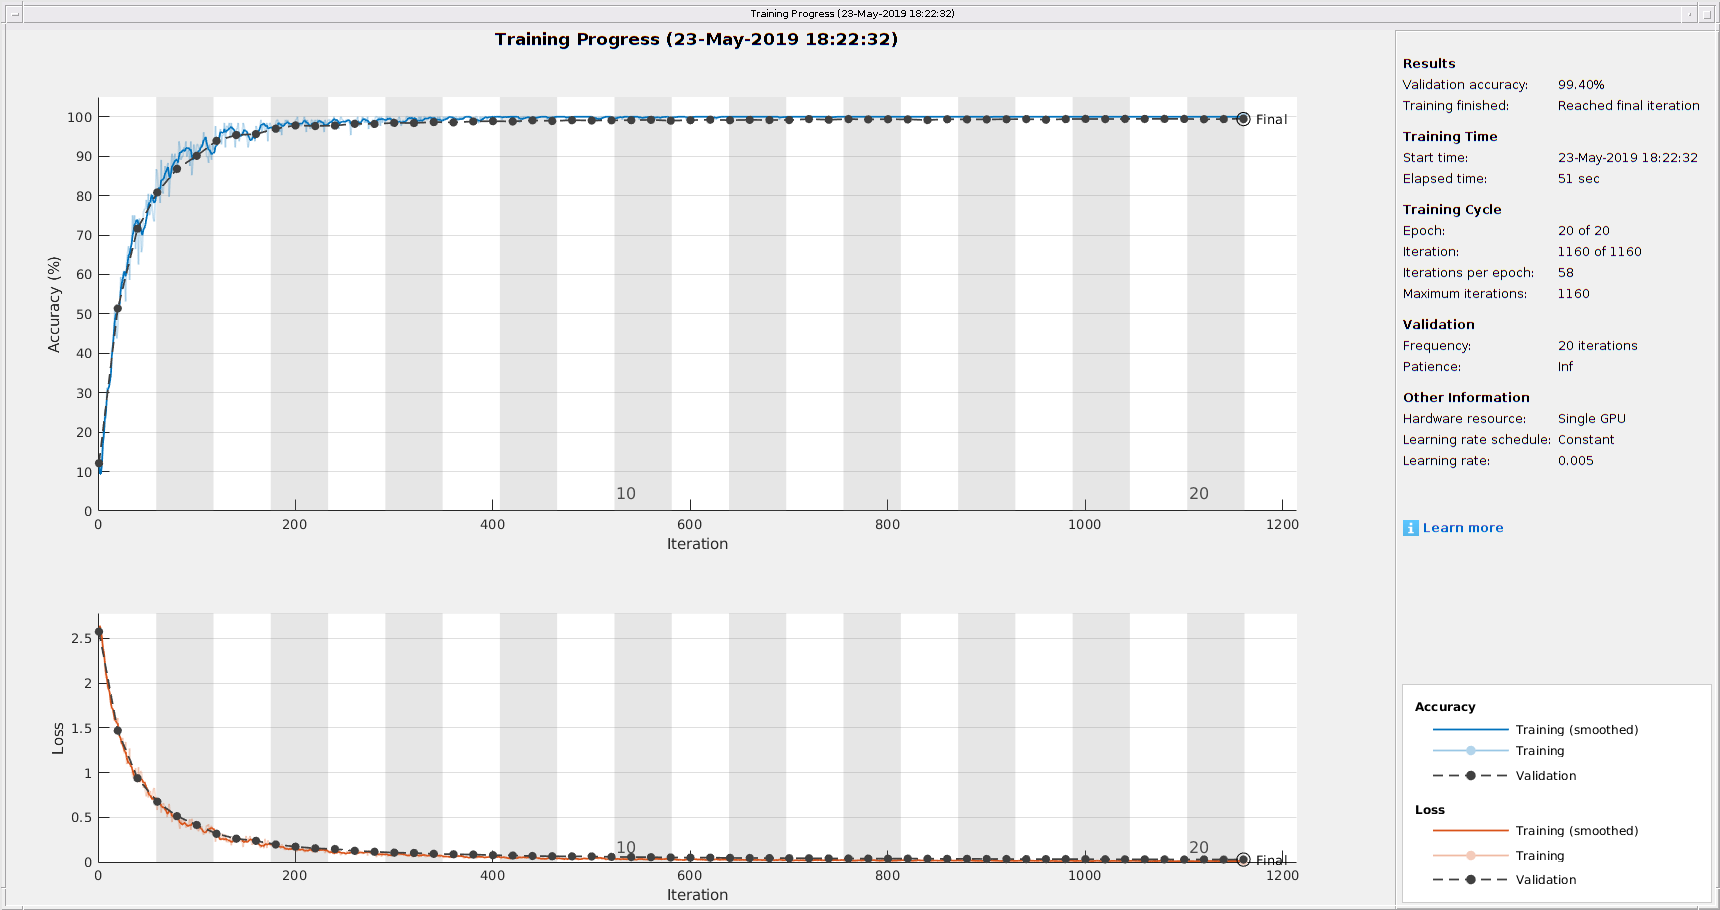

net_gpu = trainNetwork(imdsTrain,layers,option_gpu);

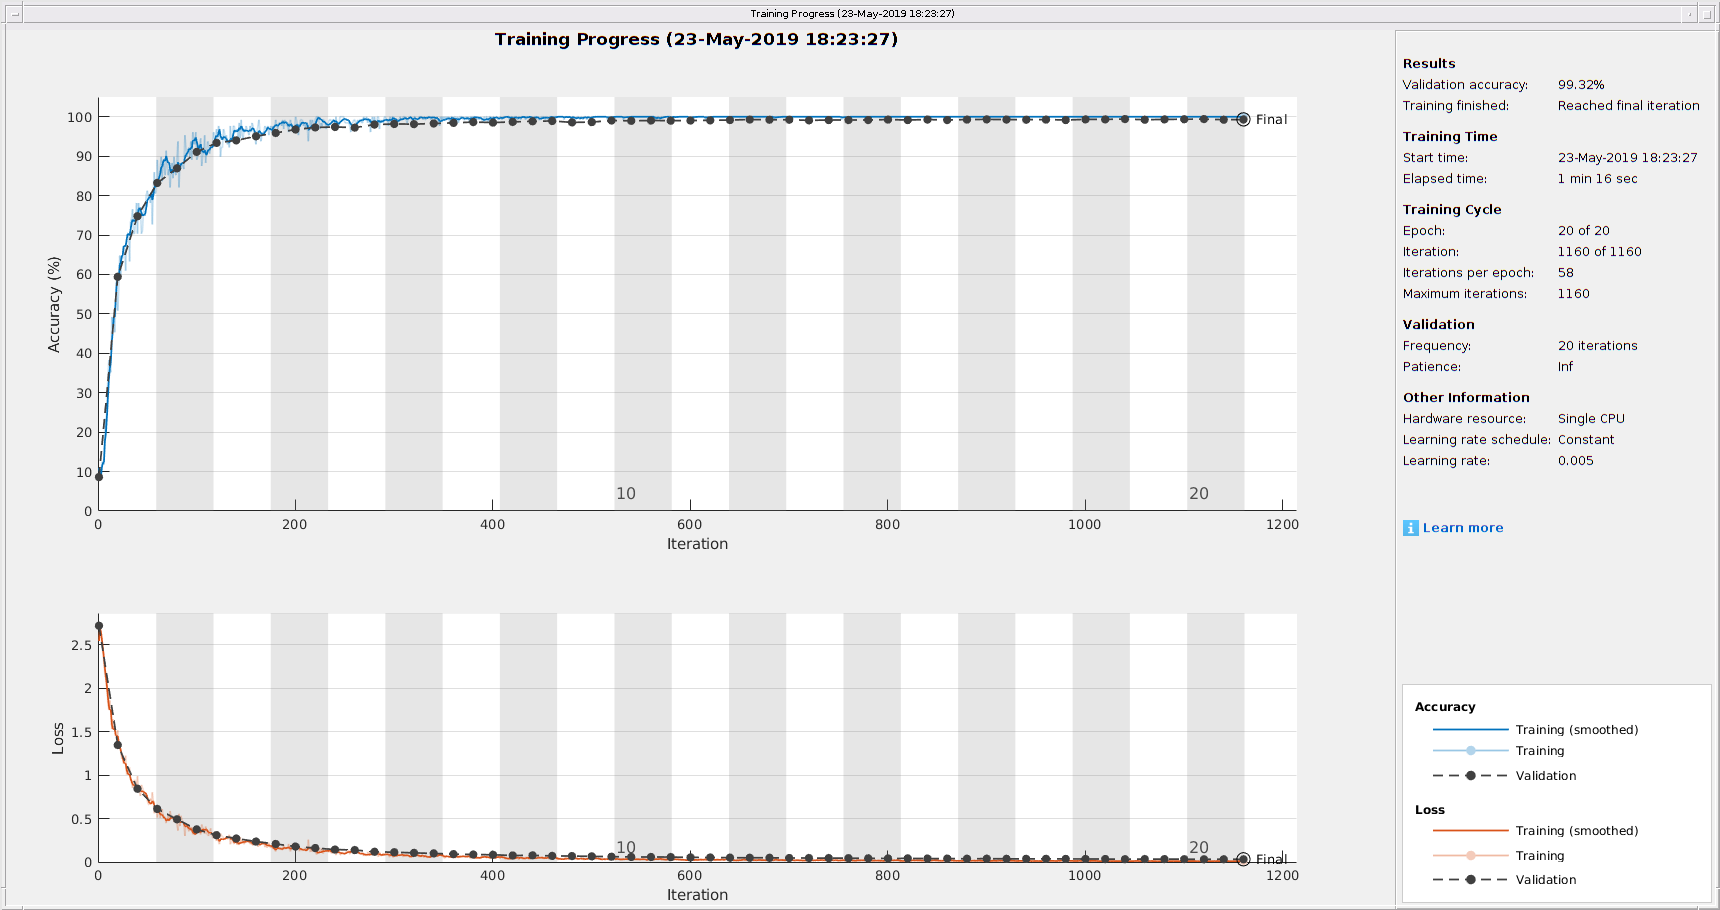

net_cpu = trainNetwork(imdsTrain,layers,option_cpu);

Entrambi gli addrestamenti delle due reti hanno prodotto un ottimo risultato, infatti entrambe posseggono un accuracy superiore del 99% per la validazione, il che significa che prese delle immagini dal dataset per la validazione, al termine dell'addestramento, la rete riesce a determinare il valore contenuto nell'immagine con una precisione prossima al 100%.

Per quanto concerne la velocità di apprendimento della rete nel caso in cui viene utilizzata un GPU, anche se la rete presa in esempio è di piccole dimensioni, è più veloce . In questo caso utilizzando la **GPU** il tempo impiegato è inferiore di circa del 60% rispetto al caso in cui venga utilizzato la **CPU.** 

### Risultati del training

Andiamo ora a collezionare i risultati ottenuti. Per semplicità, poiché le due reti sono identiche (a parte l'ambiente di esecuzione, se CPU e GPU), utilizziamo solamente la rete addestrata sulla GPU. 

Dopo aver addestrato la rete, possiamo chiamare `classify` per poter classificare gli elementi contenuti nel validation set e verificare se la predizione è corretta e con quale precisione.

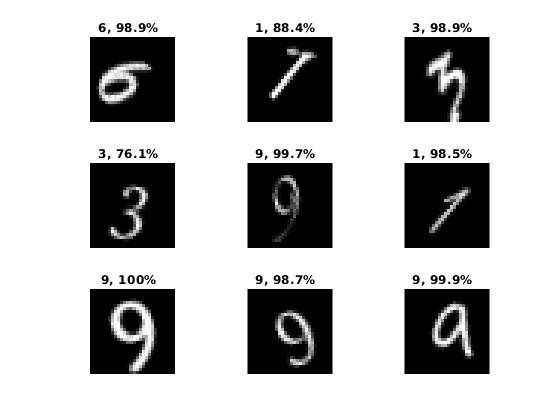

net = net_gpu;
[YPred,probs] = classify(net,imdsValidation);
YValidation = imdsValidation.Labels;
% accuracy della rete
accuracy = sum(YPred == YValidation)/numel(YValidation);

% Predizione del numero su immagini random 
figure
idx = randperm(2500,9);
for i = 1:numel(idx)
    subplot(3,3,i)
    imshow(imdsValidation.Files{idx(i)});
    prob = num2str(100*max(probs(idx(i),:)),3);
    predClass = char(YPred(idx(i)));
    title([predClass,', ',prob,'%  '])
end

## Osservazioni 

Come si può osservare, la rete addestrata 

## Riferimenti

[1] [Doc di imageDatastore](https://it.mathworks.com/help/matlab/ref/matlab.io.datastore.imagedatastore.html)

[2] [Deep Learning](https://it.mathworks.com/products/deep-learning.html)

## Autori

Cristiano Salerno, Gabriele Previtera, Andrea Abbate